G_num = [1];
G_denum = [720 1764 1624 735 175 21 1];

% G_m_num = G_num;
% G_m_denum = G_denum;
G_m_num = [1];
G_m_denum = [5 5 4 2];

Kp_r_m = 1;
Ki_r_m = 1;

Kp_r_k = 0.5;
Ki_r_k = 0.2;

t_amp = 0:0.5:10;
u_amp = 0:2:40;

out = sim("src\simulink_models\model_mfc.slx");

sys = tf(G_num, G_denum)

sys =
 
                               1
  ------------------------------------------------------------
  720 s^6 + 1764 s^5 + 1624 s^4 + 735 s^3 + 175 s^2 + 21 s + 1
 
Continuous-time transfer function.



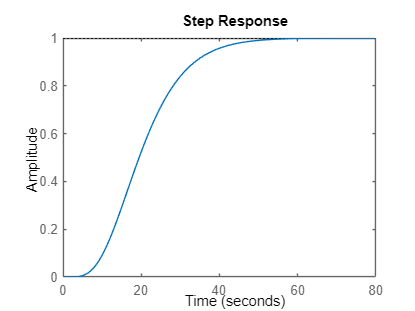

step(sys)

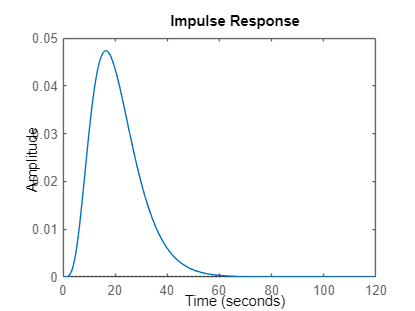

impulse(sys)

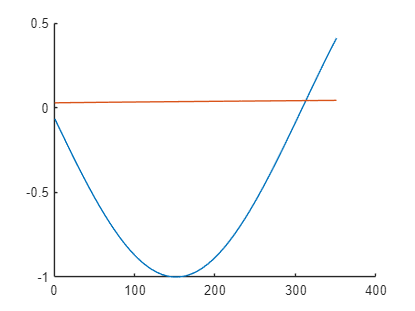

u = out.u_obiekt.signals.values(950:1300);
y = out.y_obiekt.signals.values(951:1301);

% u = out.u.signals.values(950:1000);
% y = out.y.signals.values(951:1001);

figure
hold on
plot(u)
plot(y)
hold off


% u = reshape(out.u_obiekt.signals.values, [length(out.u_obiekt.signals.values), 1]);
% y = reshape(out.y_obiekt.signals.values, [length(out.y_obiekt.signals.values), 1]);
% u = u(1:500)
% y = y(1:500)

u

u =    -0.0652
   -0.0752
   -0.0851
   -0.0951
   -0.1050
   -0.1150
   -0.1249
   -0.1348
   -0.1447
   -0.1546


y

y =     0.0288
    0.0288
    0.0289
    0.0289
    0.0290
    0.0290
    0.0291
    0.0291
    0.0292
    0.0292


U_matrix = zeros(length(u), length(u));
for i=1:length(u)
    for j=1:length(u)
        if i >= j
            U_matrix(i, j) = u(i - j + 1);
        end
    end
end
U_matrix

U_matrix =    -0.0652         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0752   -0.0652         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

inv(U_matrix)

ans =   -15.3431         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   17.6914  -15.3431         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   


% g = inv(U_matrix)*y;
g = U_matrix\y

g =    -0.4412
    0.0667
    0.0565
    0.0478
    0.0404
    0.0342
    0.0289
    0.0244
    0.0207
    0.0174


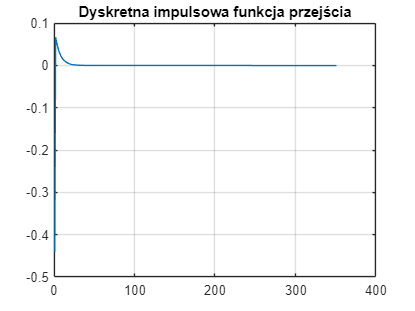

figure
plot(g)
grid on
title('Dyskretna impulsowa funkcja przejścia')

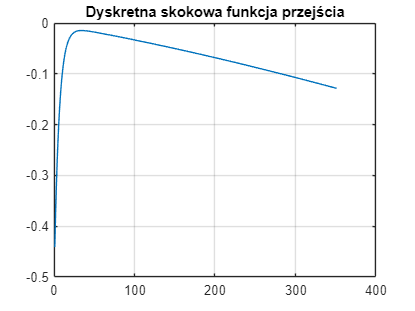


h = cumsum(g);
figure
plot(h)
grid on
title('Dyskretna skokowa funkcja przejścia')

g_new = zeros(length(out.y.signals.values), 1);
N = 60;
steps = floor(length(out.y.signals.values)/N - 1);

u = out.u_obiekt.signals.values(1:N);
y = out.y_obiekt.signals.values(2:N+1);
U_matrix = zeros(length(u), length(u));
for i=1:length(u)
    for j=1:length(u)
        if i >= j
            U_matrix(i, j) = u(i - j + 1);
        end
    end
end
g_new(1:N) = U_matrix\y;

% g_new(1:N) = inv(U_matrix)*y;

for k=1:steps
    u = out.u_obiekt.signals.values(k*N + 1:(k+1)*N);
    y = out.y_obiekt.signals.values((k*N) + 2:(k+1)*N + 1);
    U_matrix = zeros(length(u), length(u));
    for i=1:length(u)
        for j=1:length(u)
            if i >= j
                U_matrix(i, j) = u(i - j + 1);
            end
        end
    end
    g_new(k*N +  1: (k+1)*N) = U_matrix\y;
%       g_new(k*N +  1: (k+1)*N) = inv(U_matrix)*y;
end

g_new(isnan(g_new)) = 0;

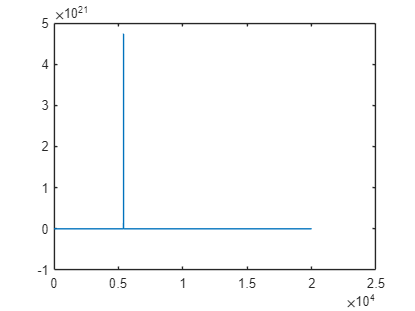

figure
plot(g_new)

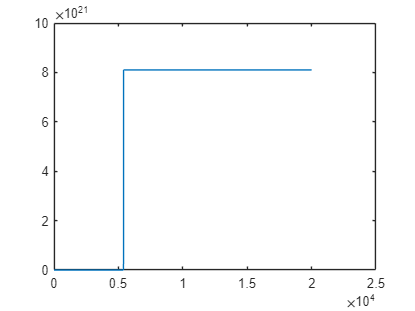


h_new = cumsum(g_new);
figure
plot(h_new)

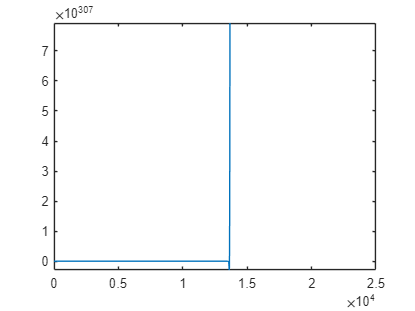

u = out.u.signals.values;
y = out.y.signals.values;
g_new = zeros(length(u), 1);
sum = 0;
for i=2:length(u)-1
    for j=1:i-1
        sum = sum + u(j)*g_new(i-j);
    end
    g_new(i) = (y(i + 1) - sum)/u(52);
    sum = 0;
end

figure
plot(g_new)

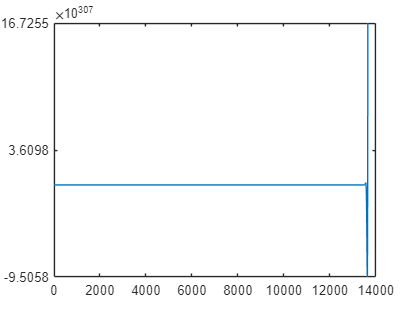


h_new_2 = cumsum(g_new);
figure
plot(h_new_2)